Caitlin and Clark

(Added from today's lecture) We are using the conservation of energy to derive our equations, starting from rate of change of energy = energy in - energy out

clear; clc; close('all');

tspan = [0 60*60*24*20]; %time in seconds, 20 days
Ti = 23; %initial floor temp in C
% TODO why at 23 degrees at 20 days we have the weird spike? 22.9 degrees
% is fine...
T_air = -3; % in C

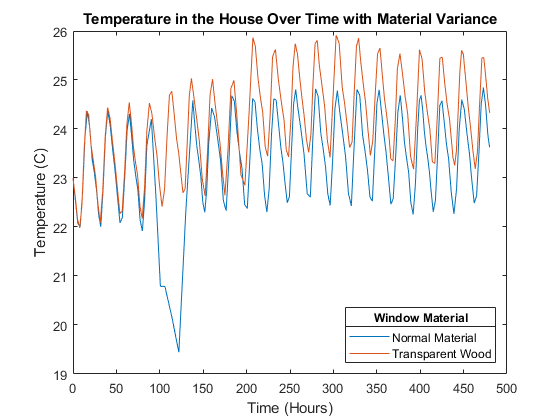

L_absorber_unchanging = [.5];
L_wall_unchanging = [.05];
figure;

for i = 1:length(L_absorber_unchanging)
    [t, T] = ode45(@(t,T) timederiv(t,T,L_absorber_unchanging(i), L_wall_unchanging(i)), tspan, Ti);
    [t2, T2] = ode45(@(t2,T2) timederiv2(t2,T2, L_absorber_unchanging(i), L_wall_unchanging(i)), tspan, Ti);
    plot((t/(60*60)),T);
    hold on;
    plot(t2/(60*60), T2)
    hold on;
end
ylabel 'Temperature (C)'
xlabel 'Time (Hours)'
title 'Temperature in the House Over Time with Material Variance'
%You may decide to convert to days
lgd = legend(["Normal Material", "Transparent Wood"]);
lgd.Title.String = 'Window Material';       
lgd.Location = 'southeast';          

Write different things here :o

We will now change L_absorber values! 

L_absorber_range = [.05:.1:.505]; % picked these values because the floor can be pretty comfortably thick
% L = [.05:.01:.505]; % walls/absorber
% TODO change window value to constant value

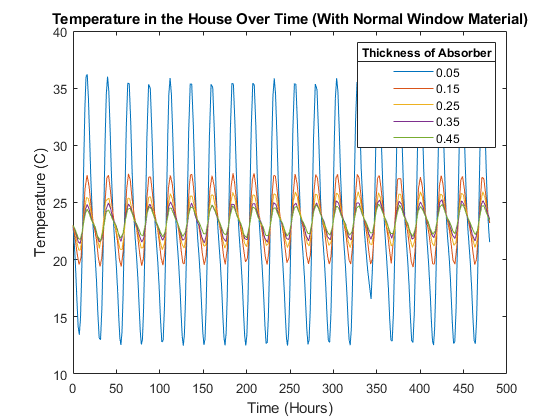

% This is the Normal Window Material
% values of L_absorber_range
figure;

for i = 1:length(L_absorber_range)
    [t3, T3] = ode45(@(t3,T3) timederiv(t3,T3, L_absorber_range(i), L_wall_unchanging(1)), tspan, Ti);
    plot((t3/(60*60)),T3)
    hold on;
end

hold off;
ylabel 'Temperature (C)'
xlabel 'Time (Hours)'
title 'Temperature in the House Over Time (With Normal Window Material)';
lgd = legend(string(L_absorber_range));
lgd.Title.String = 'Thickness of Absorber';

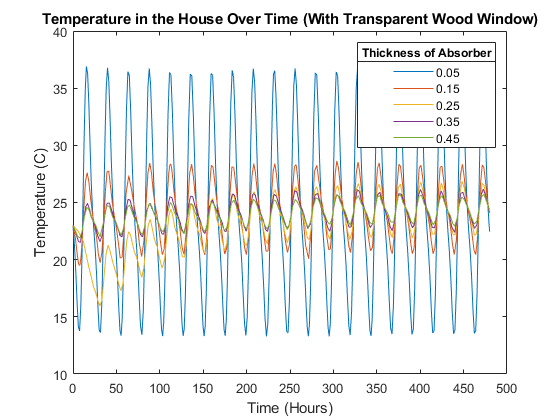

% This is the Transparent Wood 
% values of L_absorber_range
figure;

for i = 1:length(L_absorber_range)
    [t4, T4] = ode45(@(t4,T4) timederiv2(t4,T4, L_absorber_range(i), L_wall_unchanging(1)), tspan, Ti);
    plot((t4/(60*60)),T4)
    hold on;
end

hold off;
ylabel 'Temperature (C)'
xlabel 'Time (Hours)'
title 'Temperature in the House Over Time (With Transparent Wood Window)';
lgd = legend(string(L_absorber_range));
lgd.Title.String = 'Thickness of Absorber';

We are varying L_wall!

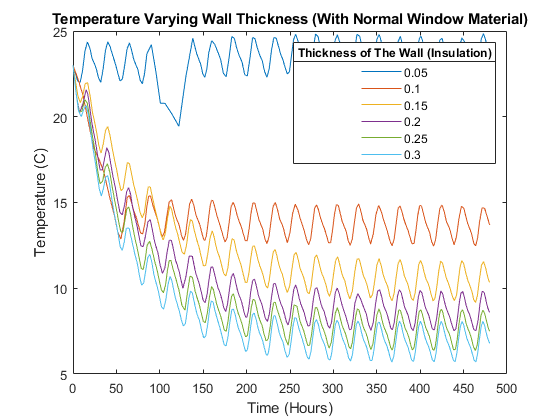

L_absorber_unchanging = [.5];
L_wall_range = [.05:.05:.3];
% This is L_wall for Normal Window Material 
% values of L_wall_range

figure;

for i = 1:length(L_wall_range)
    [t5, T5] = ode45(@(t5,T5) timederiv(t5,T5, L_absorber_unchanging(1), L_wall_range(i)), tspan, Ti);
    plot((t5/(60*60)),T5)
    hold on;
end

hold off;
ylabel 'Temperature (C)'
xlabel 'Time (Hours)'
title 'Temperature Varying Wall Thickness (With Normal Window Material)';
lgd = legend(string(L_wall_range));
lgd.Title.String = 'Thickness of The Wall (Insulation)';

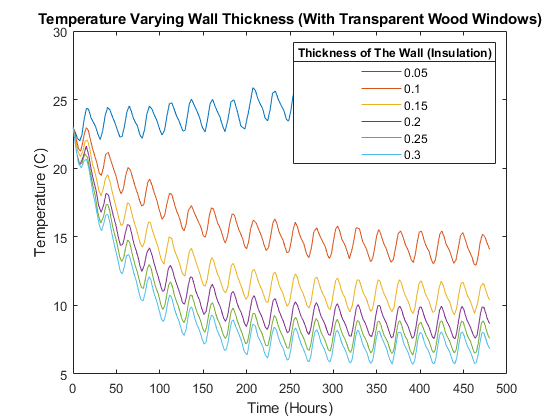

L_absorber_unchanging = [.5];
L_wall_range = [.05:.05:.3];
% This is L_wall for Normal Window Material 
% values of L_wall_range

figure;

for i = 1:length(L_wall_range)
    [t5, T5] = ode45(@(t5,T5) timederiv2(t5,T5, L_absorber_unchanging(1), L_wall_range(i)), tspan, Ti);
    plot((t5/(60*60)),T5)
    hold on;
end

hold off;
ylabel 'Temperature (C)'
xlabel 'Time (Hours)'
title 'Temperature Varying Wall Thickness (With Transparent Wood Windows)';
lgd = legend(string(L_wall_range));
lgd.Title.String = 'Thickness of The Wall (Insulation)';